Here is an example that convolves two simple functions, x and h:

% Preliminary example
N=25; % length of data vector
n=1:N; % indices
h(n)=1.05.^(n); % impulse response (growing)
x=zeros(N,1); % initializes x, the input.
x(10)=1; % replaces the first value of x with 1; happens to be an impulse
x(2:6) = 1;
y=conv(x,h) % conv performs convolution stem(y(1:N))

y =          0
    1.0500
    2.1525
    3.3101
    4.5256
    5.8019
    6.0920
    6.3966
    6.7164
    8.1023


Here is some starter code for the lab:

% read in the impulse response
     [Y1,FS1] = audioread('impulse1.wav')

Y1 =          0         0
         0         0
         0         0
    0.0000         0
   -0.0001         0
    0.0001         0
   -0.0000         0
         0    0.0000
         0   -0.0000
    0.0000   -0.0000


FS1 = 44100

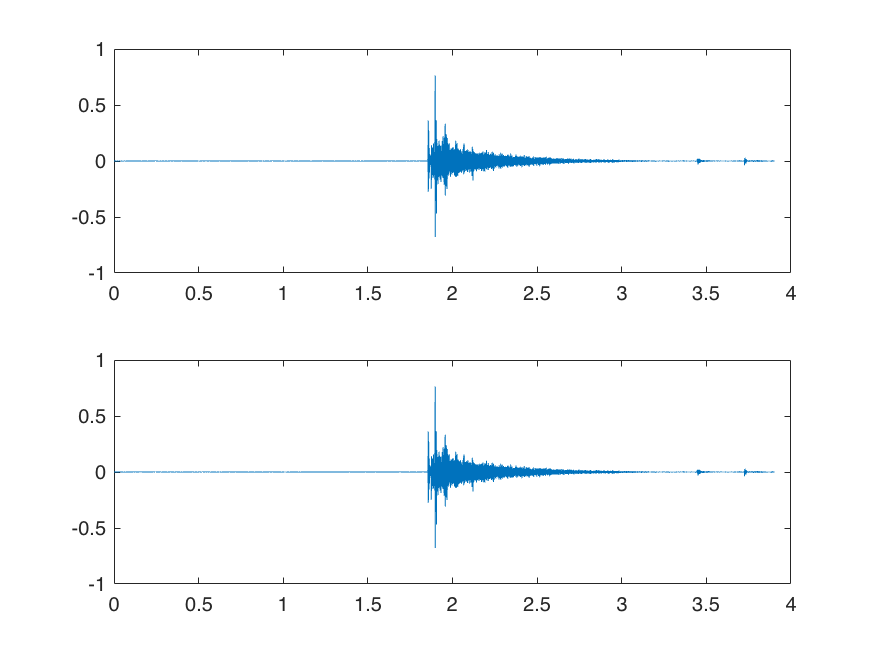

 
  % read out right and left channels
  Y1a=Y1(:,1);
  Y1b=Y1(:,2);
  h = Y1a; % define the impulse response to be one of the channels
  
  % Explore h
 
  %%%% define time vector
  N=length(Y1a);
  Ts=1/FS1;
  time=(1:N)*Ts;
 
  %%%% plot data
  subplot(2,1,1), plot(time, Y1a)
  subplot(2,1,2), plot(time, Y1b)

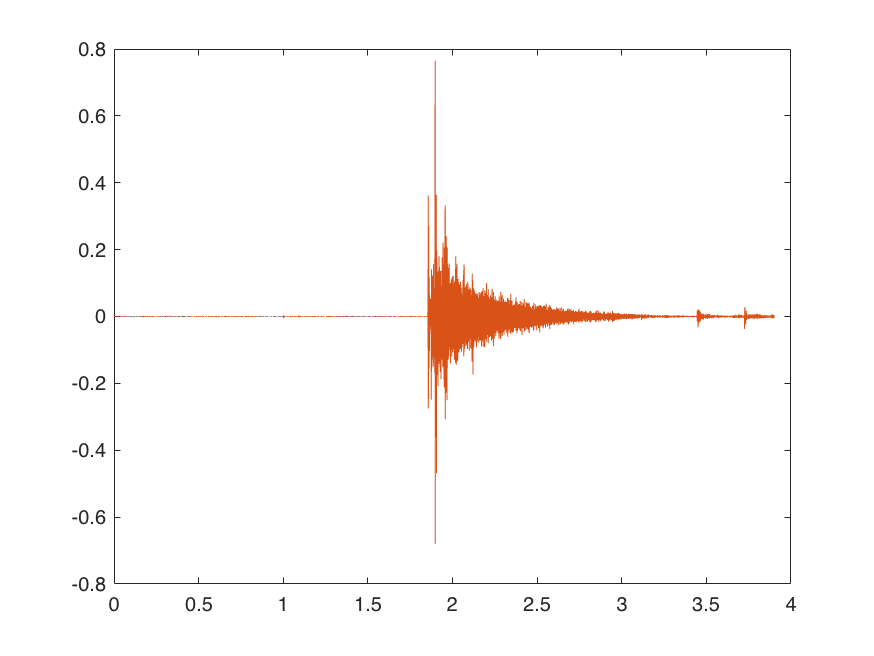

  figure
  plot(time, Y1a, time, Y1b)


   soundsc(h,FS1)
 






% To do next: read in the input waveform, x, and plot the right and left channels  
    [Y2,FS2] = audioread('Eartha Kitt - Santa Baby (Official Audio).mp3')

Y2 =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


FS2 = 44100

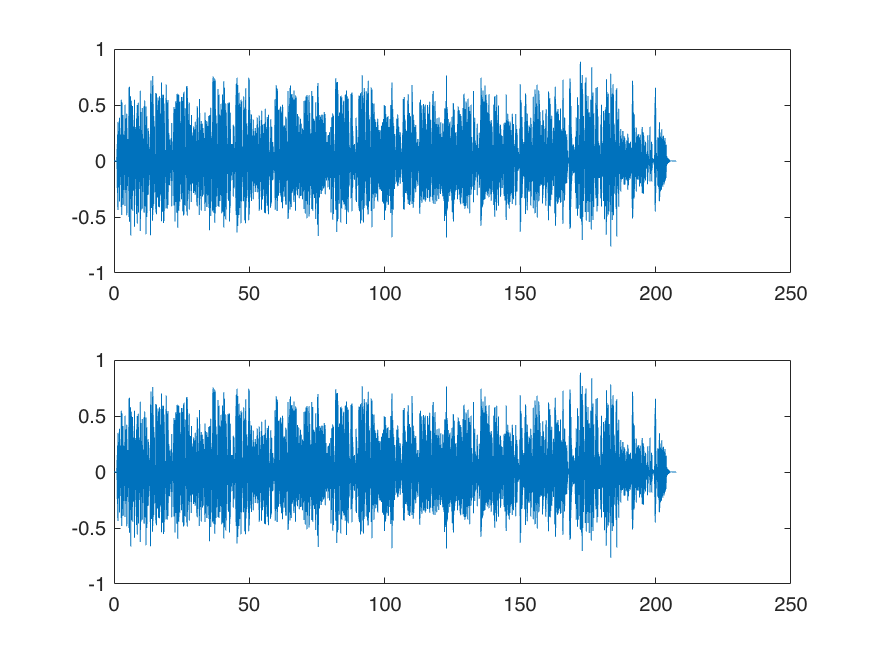


  Y2a=Y2(:,1);
  Y2b=Y2(:,2);
  x = Y2a; 
  
  
  % define the impulse response to be one of the channels
  N=length(Y2a);
  Ts=1/FS2;
  time=(1:N)*Ts;

%(very similar to the above)

  subplot(2,1,1), plot(time, Y2a)
  subplot(2,1,2), plot(time, Y2b)

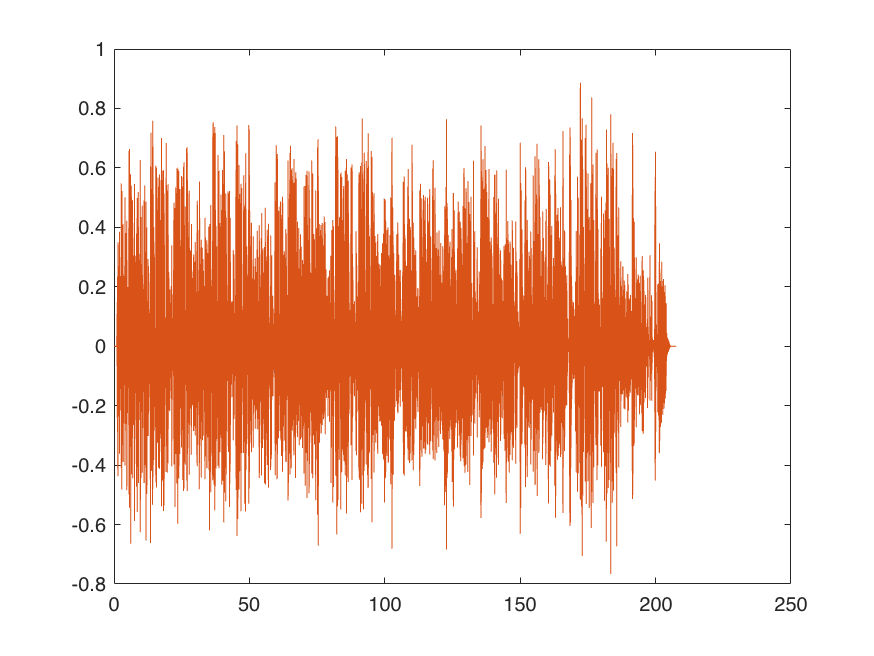

  figure
  plot(time, Y2a, time, Y2b)



  %this play original sound
   %soundsc(x,FS2)
 

  % convolve the above waveforms, x and h, using the "conv"
 waveform = conv(x,h)

waveform =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


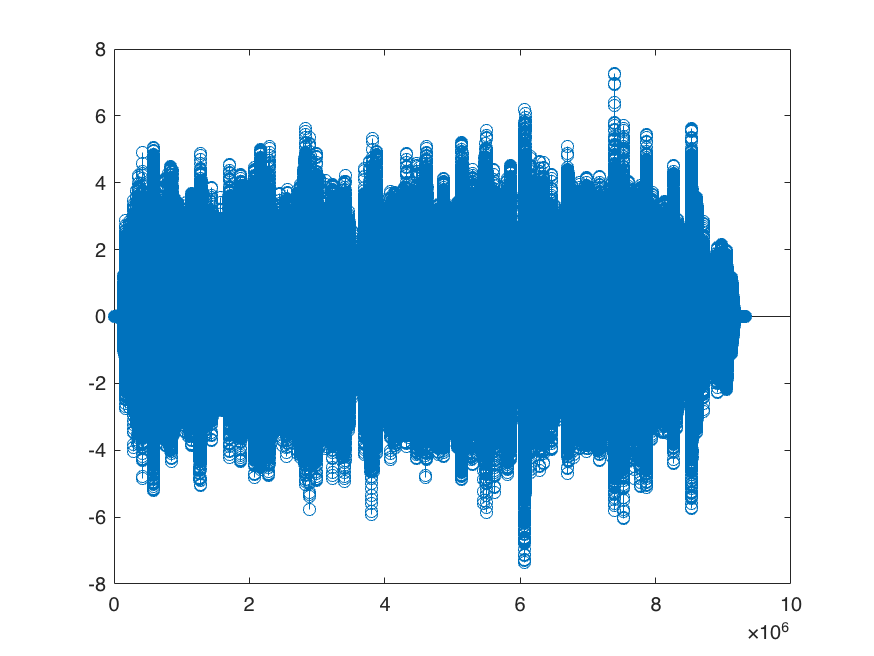

  % function.  Plot the result
  stem(waveform)

 
  % use the sound command to listen to the original and convolved outputs
 
  
  % plays the convoluted sound
  soundsc(waveform, FS2)


